# **Model-Based Volatility Estimation**

In this example we obtain volatility estimates by creating parametric time-series models. One disadvantage of the previous approach for volatility estimation using the exponentially-weighted moving average is that it does not provide volatility forecasts. However, a model-based approach can be used to create volatility forecasts.

This example focusses on the [`ARIMA`](matlab: doc arima) and [`GARCH`](matlab: doc garch) time-series models.

*Copyright 2022 The MathWorks, Inc.*

## Load the commodity data.

load( "Commodities.mat" )
commodityNames = string( InferredVolatility.Properties.VariableNames );

## Compute the principal components of the inferred volatility.

First, normalize the volatility series and store the mean and standard deviation for later use.

[normalizedVolatility, mu, sigma] = normalize( InferredVolatility.Variables, "zscore" );

Next, compute the principal components using the [`pca`](matlab: doc pca) function.

[coeffs, scores, eigVals] = pca( normalizedVolatility );

Visualize the eigenvalues of the covariance matrix of the normalized volatilities.

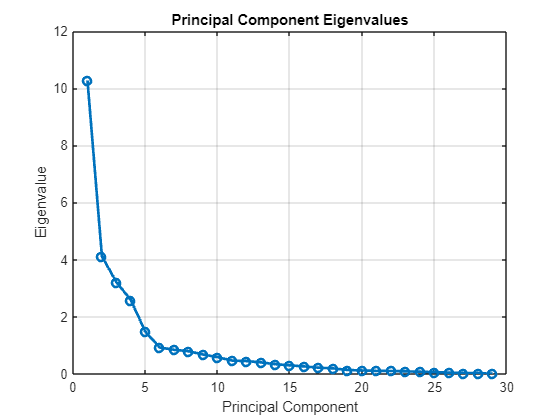

figure
plot( eigVals, "o-", "LineWidth", 2 )
xlabel( "Principal Component" )
ylabel( "Eigenvalue" )
title( "Principal Component Eigenvalues" )
grid( "on" )

We see that most of the variance in the data has been captured by the first few principal components.

Visualize the first few principal components.

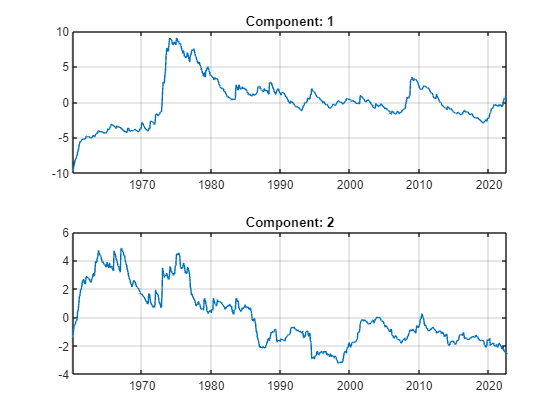

numComponents = 2;

figure
tiledlayout( "flow" )

for k = 1:numComponents
    nexttile
    plot( InferredVolatility.Date, scores(:, k ) )
    title( "Component: " + k )
    grid( "on" )
end

## Model the principal components.

Rather than creating many separate time-series models for each commodity, an efficient approach is to build models only for the first few principal components. Forecasts from these models can then be back-transformed into the original domain. 

Create and fit a time-series model for the first principal component.

firstComponent = scores(:, 1);

firstComponentModel = arima( "ARLags", 1, ...
    "MALags", 1, ...
    "Distribution", "t", ...
    "Variance", garch( 1, 1 ) );
firstComponentModel = estimate( firstComponentModel, firstComponent );

 
    ARIMA(1,0,1) Model (t Distribution):
 
                 Value      StandardError    TStatistic      PValue  
                ________    _____________    __________    __________

    Constant    -0.06307      0.0064023       -9.8511      6.7807e-23
    AR{1}        0.98278      0.0020414        481.44               0
    MA{1}        0.13458        0.02814        4.7826      1.7306e-06
    DoF           2.5261        0.23103        10.934      7.9373e-28

 
 
    GARCH(1,1) Conditional Variance Model (t Distribution):
 
                  Value      StandardError    TStatistic      PValue  
                _________    _____________    __________    _____

Create and fit a time-series model for the second principal component.

secondComponent = scores(:, 2);
secondComponentModel = arima("ARLags", 1, ...
    "MALags", 1, ...
    "Distribution", "t", ...
    "Variance", garch( "ARCHLags", 1, ...
    "Constant", 0.01, ...
    "GARCHLags", 1 ) );
secondComponentModel = estimate( secondComponentModel, secondComponent );

 
    ARIMA(1,0,1) Model (t Distribution):
 
                  Value      StandardError    TStatistic      PValue   
                _________    _____________    __________    ___________

    Constant    -0.025893      0.0044551        -5.812       6.1741e-09
    AR{1}         0.98148      0.0024963        393.18                0
    MA{1}        0.055741       0.025195        2.2124         0.026942
    DoF            2.1631       0.081496        26.543      3.1333e-155

 
 
    GARCH(1,1) Conditional Variance Model (t Distribution):
 
                 Value      StandardError    TStatistic      PValue   
                ________    _____________    __________    <s

## Create simulated component values from the fitted models.

numForecastSteps = 60;
simFirstComponent = simulate( firstComponentModel, numForecastSteps, "Y0", firstComponent );
simSecondComponent = simulate( secondComponentModel, numForecastSteps, "Y0", secondComponent );
simComponents = [simFirstComponent, simSecondComponent];

## Back-transform the simulated component values.

Transform the simulation results in the principal component domain back to the original volatility domain, adjusting for the normalization step performed above. Since we have only modelled the first two principal components, this transformation is an approximation to the volatility. Modelling more of the principal components would lead to a more accurate volatility approximation at the cost of more modelling, simulation and execution time.

approxVolatility = mu + sigma .* (simComponents * coeffs(:, 1:2).');
approxVolatility = [InferredVolatility{end, :}; approxVolatility];

Convert the volatility approximations to the timetable format.

simDates = InferredVolatility.Date(end) + calmonths(0:numForecastSteps).';
approxVolatility = array2timetable( approxVolatility, ...
    "RowTimes", simDates, "VariableNames", commodityNames );
approxVolatility.Properties.DimensionNames(1) = "Date";

## Visualize the volatility simulation results.

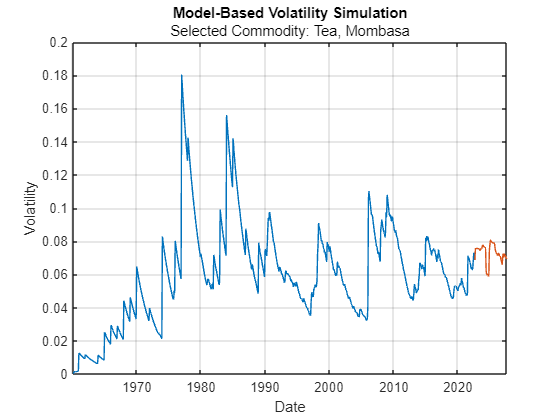

selectedCommodity = commodityNames(7);

figure
plot( InferredVolatility.Date, InferredVolatility.(selectedCommodity) )
hold on
plot( approxVolatility.Date, approxVolatility.(selectedCommodity) )
xlabel( "Date" )
ylabel( "Volatility" )
title( "Model-Based Volatility Simulation" )
subtitle( "Selected Commodity: " + selectedCommodity )
grid on